# Relatório IV - MOAB

Análise e Projeto de Sistemas de Controle - 20.1

Professor Antonio Marcus Nogueira Lima, Dr. 

Aluno: Arthur Dimitri Brito Oliveira

Este relatório tem como objetivo a apresentação do desenvolvimento do modelo matemático do MOAB, um sistema bola-prato com múltiplos graus de liberdade. Além disso, busca-se a comparação entre a implementação do modelo matemático do MOAB e a implementação computacional disponível em um repositório do GitHub. 

## Sumário

- **Introdução **

- **Fundamentação Teórica**

-     Premissas quanto ao modelo dinâmico

-     Nomenclatura utilizada

-     Equações de movimento: derivação

-     Análise cinemática das juntas

- **Desenvolvimento **

- **Referências **   

## Introdução

O balanceamento de uma bola sobre um prato é um problema de controle desafiador. Trata-se de um sistema não linear complexo com múltiplos graus de liberdade. A Figura 1 ilustra o sistema.

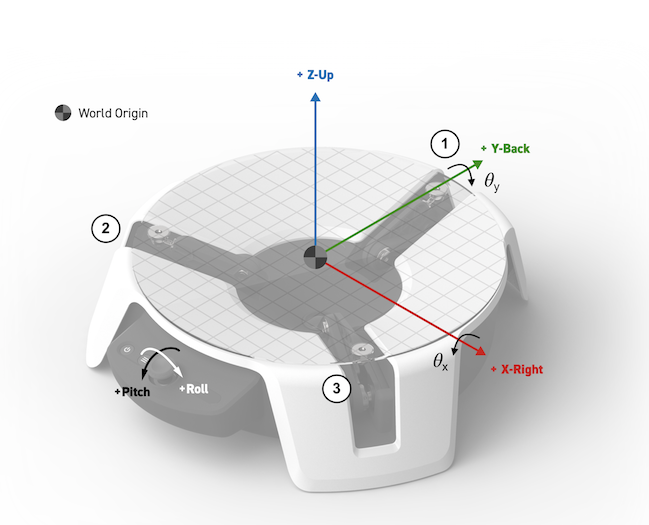

Figura 1: Vista isométrica do sistema bola-prato com identificação dos eixos. 

O sistema consiste em um prato que pode ser atuado, a partir do acionamento de três motores, em duas direções perpendiculares. O projeto é realizado de tal modo que o centro do prato não se move. O objetivo consiste na estabilização da bola em um ponto de operação desejado no prato, ou fazer com que a bola siga uma trajetória pré-definida. Há quatro graus de liberdade: dois associados às inclinações do prato e dois relacionados ao movimento da bola nos eixos $x$ e $y$ do prato. 

## Fundamentação Teórica

Esta seção trata da formulação matemática do problema.

### **Premissas quanto ao modelo dinâmico**

Algumas premissas são estabelecidas para simplificar a modelagem do sistema:

- A bola nunca perde contato com a superfície do prato.

- Não há deslizamento entre a bola e o prato. 

- Forças de atrito são desprezíveis. 

### Nomenclatura utilizada

Para as variáveis do sistema, utilizou-se as seguintes nomenclaturas:

- $\theta_y$ - ângulo com relação ao eixo $X$

- $\dot \theta_y$ - velocidade angular do prato com relação ao eixo $X$

- $\ddot \theta_y$ - aceleração angular do prato com relação ao eixo $X$

- $\theta_x$ - ângulo com relação ao eixo $Y$

- $\dot \theta_x$ - velocidade angular do prato com relação ao eixo $Y$

- $\ddot \theta_x$ - aceleração angular do prato com relação ao eixo $Y$

- $m_b$ - massa da bola

- $J_b$ - momento de inércia da bola 

- $r_b$ - raio da bola

- $v_b$ - velocidade da bola

- $x$ - posição da bola no eixo x 

- $y$ - posição da bola no eixo y 

- $\dot x$ - velocidade da bola no eixo x

- $\dot y$ - velocidade da bola no eixo y

- $\ddot x$ - aceleração da bola no eixo x

- $\ddot y$ - aceleração da bola no eixo y

### Equações de movimento: derivação

Para esta seção, utitilizou-se a modelagem matemática proposta em [1]. A formulação Lagrangiana utiliza escalares e torna a transformação de coordenadas uma tarefa mais simples. O Lagrangiano pode ser definido como:


$$\mathcal{L} = T - V$$


Onde $T$ é a energia cinética do sistema e $V$ é a energia potencial do sistema. A energia cinética total do sistema tem quatro componentes: energia cinética translacional da bola com relação à origem do prato; a energia rotacional da bola com relação ao seu centro de gravidade; energia cinética translacional do prato; energia cinética rotacional da bola no sistema bola-prato com relação à origem do prato. 

Tratando da energia translacional da bola com relação à origem do prato, a posição da bola pode ser escrita como:


$$\vec{r} = x\hat i + y\hat j + (x\sin(\theta_y) + y\sin(\theta_x))$$


Ao derivar a equação anterior, tem-se:


$$\dot \vec{r} = (\dot x \sin(\theta_y) + x\dot \theta_y\cos(\theta_y) + \dot y \sin(\theta_x) + y\dot \theta_x \cos(\theta_x))$$


Ao utilizar a expansão por série de Taylor para $\sin(\theta_y), \sin(\theta_x) \:\: e \:\: \cos(\theta_y), \cos(\theta_x)$ em torno do ponto de equilíbrio, tem-se que:


$$[\theta_y \:\:\:\: \theta_x]' = [0 \:\:\:0]'$$


De modo que:


$$\vec r = \dot x \hat i + \dot y \hat j + (-x\dot \theta_y + y\dot \theta_x)\hat k$$


O módulo do vetor de posição é:


$$|\dot r| = \sqrt{\dot x^2 + \dot y^2 + (-x \dot \theta_y + y\dot \theta_x)^2}$$


A energia cinética translacional é dada por:


$$T_{bt} = \frac{1}{2}m_b(\dot x^2 + \dot y^2 + (-x\dot \theta_y + y\dot \theta x)^2)$$


A energia cinética rotacional da bola em relação ao seu centro de gravidade pode ser escrita como:


$$T_{br} = \frac{1}{2}J_b\omega_b^2$$


Tendo em vista que não há separação entre a bola e o prato, a velocidade dela em relação ao prato é zero, de modo que $\omega_b=\frac{v_b}{r_b}$. A velocidade da bola,  $v_b$ pode ser definida como:


$$\vec{v_b} = \dot x\hat i+ \dot y \hat j \rightarrow |v_b| = \sqrt{\dot x^2 + \dot y^2}$$


Sendo assim, a energia rotacional da bola em relação ao seu centro de gravidade é:


$$T_{br} = \frac{1}{2}\frac{J_b}{r_b^2}(\dot x^2 + \dot y^2)$$


Analisando então a energia cinética rotacional do sistema bola-prato com relação à origem do prato, constata-se que a energia total consiste em três elementos: a energia cinética da bola, a energia cinética devido aos momentos de inércia do prato em $x$ e a energia cinética devido aos momentos de inércia do prato na direção de $y$. Assim:


$$T_{pb} = \frac{1}{2}J_b(\dot\theta_y^2 + \dot \theta_x^2) + \frac{1}{2}J_{px}\dot \theta_y^2 + \frac{1}{2}J_{py}\dot \theta_x^2$$


Onde $J_{px}$ e $J_{py}$ são os momentos de inércia do prato com relação aos eixos $X$ e $Y$ respectivamente. $\theta_y$ e $\theta_x$ são as inclinações do prato com relação aos eixos $X
$ e $Y$. 

A energia potencial do sistema, relativa ao plano de equilíbrio, pode ser expressa como: 


$$V = m_bg(-x\sin\theta_y + y\sin(\theta_x))$$


Utilizando a formulação Lagrangiana e derivando as equações de movimento, tem-se que:


$$\mathcal{L} = T_{bt} + T_{br} + T_{pb} - V$$


Substituindo as expressões de $T_{bt}, \:\:T_{br},\:\: T_{pb}  \;\: e\:\: V$, tem-se:


$$\mathcal{L} = \frac{1}{2}(m_b + \frac{J_b}{r_b^2})(\dot x^2 + \dot y^2) + \frac{1}{2}m_b(x\dot \theta_y - y\dot \theta_x)^2 + \frac{1}{2}J_b(\dot \theta_y^2 + \dot \theta_x^2) + \frac{1}{2}J_{px}\dot \theta_x^2 +  \frac{1}{2}J_{py}\dot \theta_y^2  -m_bg(-x\sin \theta_y + y\sin \theta_x)$$


Utilizando a formulação Lagrangiana, e estabelecendo as coordenadas como $q_1=x \:\:e  \:\: q_2=y$, obtem-se:


$$\frac{d}{dt}(\frac{\delta\mathcal{L}}{\delta\dot x_i}) - \frac{\delta\mathcal{L}}{\delta x_i} = F_x$$



$$\frac{d}{dt}(\frac{\delta\mathcal{L}}{\delta\dot y_i}) - \frac{\delta\mathcal{L}}{\delta y_i} = F_y$$


Para $q_i = x$:


$$\frac{\delta\mathcal{L}}{\delta \dot x} = (m_b + \frac{J_b}{r_b^2})\dot x$$



$$\frac{d}{dt}(\frac{\delta\mathcal{L}}{\delta \dot x}) = (m_b + \frac{J_b}{r_b^2})\ddot x$$



$$\frac{\delta\mathcal{L}}{\delta  x} = m_b\dot \theta_y(x\dot \theta_y- y\dot \theta_x) + m_bg\sin\theta_y$$


Para $q_i=y$:


$$\frac{\delta \mathcal{L}}{\delta \dot y} = (m_b + \frac{J_b}{r_b^2})\dot y$$



$$\frac{d}{dt}(\frac{\delta \mathcal{L}}{\delta \dot y}) = (m_b + \frac{J_b}{r_b^2})\ddot y$$



$$\frac{\delta\mathcal{L}}{\delta y} = m_b\dot \theta_x(y\dot \theta_x - x\dot\theta_y) - m_bg\sin{\theta_x}$$


Sabendo que não há quaisquer forças externas em $x
$ e em $y$, $F_x,F_y=0$. De forma que:


$$\frac{d}{dt}(\frac{\delta\mathcal{L}}{\delta\dot x}) - \frac{\delta\mathcal{L}}{\delta x} = F_x = 0$$



$$\frac{d}{dt}(\frac{\delta\mathcal{L}}{\delta\dot x}) - \frac{\delta\mathcal{L}}{\delta x}  = (m_b + \frac{J_b}{r_b^2})\ddot x 

- m_b\dot \theta_y(x\dot \theta_y- y\dot \theta_x) - m_bg\sin\theta_y = 0$$



$$\frac{d}{dt}(\frac{\delta\mathcal{L}}{\delta\dot y}) - \frac{\delta\mathcal{L}}{\delta y}  = (m_b + \frac{J_b}{r_b^2})\ddot y 

- m_b\dot \theta_x(y\dot \theta_x-x\dot \theta_y) + m_bg\sin\theta_y = 0$$


Isolando as derivadas de segunda ordem, tem-se:


$$\ddot x = \frac{m_b(x\dot \theta_y^2 - y\dot \theta_x\dot \theta_y + g\sin\theta_y)}{mb+\frac{J_b}{r_b^2}}$$



$$\ddot y = \frac{mb(y\dot \theta_x^2 + x\dot\theta_x\dot\theta_y - g\sin\theta_x)}{m_b+J_br_b^2}$$


### Análise Cinemática das Juntas

A Figura 2 ilustra um corte transversal da planta em relação ao eixo de um dos motores. 

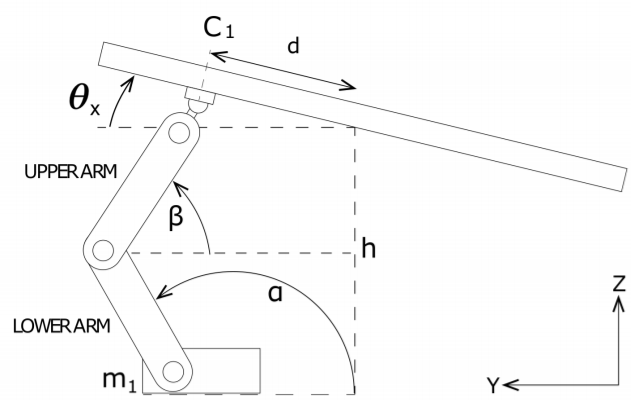

Figura 2: Corte transversal do sistema com relação ao motor 1. 

A figura abaixo ilustra a vista superior do sistema e o posicionamento das juntas. 

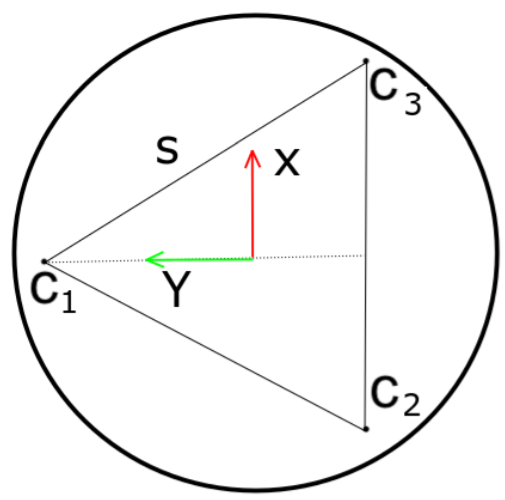

Figura 3: Vista superior do triângulo equilátero formado pelos pontos onde as juntas estão acopladas ao prato. 

A altura no eixo Z pode ser então definida por:


$$Z_{c1} = h + \frac{S\cos(30º )}{2}\sin(\theta_x)$$



$$Z_{c1} = h + \frac{S}{\sqrt3}\sin(\theta_x)$$


Alternativamente, $Zc_1 $pode ser escrito como:


$$Zc_1 = l\sin\alpha + l\sin\beta = 2l\sin\alpha_1$$



$$\alpha_1=\arcsin(\frac{zc_1}{2l})$$


A Figura 4 ilustra um corte transversal com relação aos motores 2 e 3. 

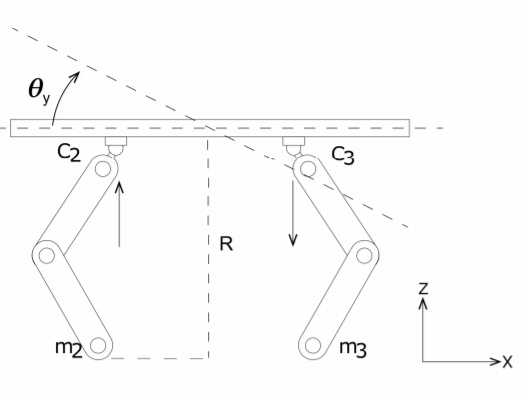

Figura 4: Seção transversal às juntas 2 e 3.

A altura no eixo z dos pontos  $Zc_2$ e $Zc_3$ é expressa por:


$$Zc_2 = R + \frac{s}{\sqrt3}\sin\theta_y$$



$$Zc_3 = R - \frac{s}{\sqrt3}\sin\theta_y$$



$$R = h - \frac{s}{s\sqrt3}\sin\theta_x$$



$$\alpha_2 = \arcsin{\frac{Zc_2}{2l}}$$



$$\alpha_3 = \arcsin\frac{Zc_3}{2l}$$


Os ângulos $\alpha_{1,2,3}$ são equivalentes aos ângulos dos motores servo $m_{1,2,3}$. Para evitar singularidades no sistema, força-se $\alpha_{1,2,3}$ a operar na região de 90 a -145º. 

### Desenvolvimento 

Após a validação das equações referentes ao modelo dinâmico do MOAB, bem como da análise da cinemática das juntas, verificou-se a compatibilidade destas com o modelo proposto por CITAR REPOSITORIO DO MOAB. 

De modo a validar as equações, o sistema foi representado de duas formas: utilizando o Simscape e o Simulink, implementando no segundo as equações diferenciais que descrevem o sistema. Para analisar a posição da bola de forma comparativa entre as duas simulações, estabeleceu-se em malha fechada valores de referência para o ângulo em relação ao eixo $x
$, $\theta_y$ e o ângulo com relação ao eixo $y$, $\theta_x$. Os valores de referência adotados para uma simulação de dois segundos podem ser visualizados na Figura 5. 

initializeMoab

showing Mechanics Explorer


MOAB_PARAMS

out = sim('MyMOAB')

out =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                 simlog: [1x1 simscape.logging.Node] 
                 simout: [1x1 timeseries] 
                   tout: [550x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


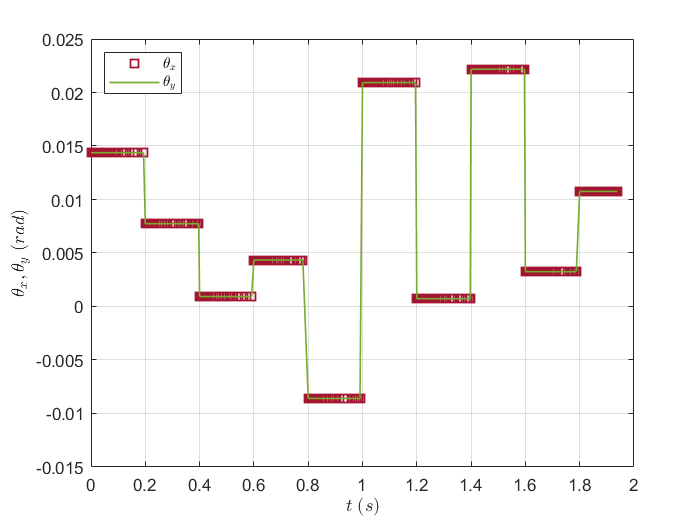

tx = out.simout.Data(:,1,:); tx = tx(:,:);
ty = out.simout.Data(:,2,:); ty = ty(:,:);
x2 = out.simout.Data(:,3,:); x2 = x2(:,:);
x1 = out.simout.Data(:,4,:); x1 = x1(:,:);
y2 = out.simout.Data(:,5,:); y2 = y2(:,:);
y1 = out.simout.Data(:,6,:); y1 = y1(:,:);
t = out.simout.time;

figure();
plot(t,tx,'s','color','#A2142F','LineWidth',1), hold on;
plot(t,ty,'-','color','#77AC30','LineWidth',1), hold off;
ylabel('$\theta_x,\theta_y\; (rad)$','Interpreter','Latex');
ylim([-0.015 0.025])
xlabel('$t\;(s)$','Interpreter','Latex');
legend('$\theta_x$','$\theta_y$','Interpreter','Latex',...
        'Location', "northwest"); grid;

Figura 5: Referências impostas para os ângulos $\theta_x \:\: e \:\: \theta_y$.

Ao utilizar estes valores como referência em malha fechada, observou-se a posição da bola no prato com relação aos eixos $x 
$ e $y$ para dois segundos de simulação.  O resultado pode ser observado na Figura 6. 

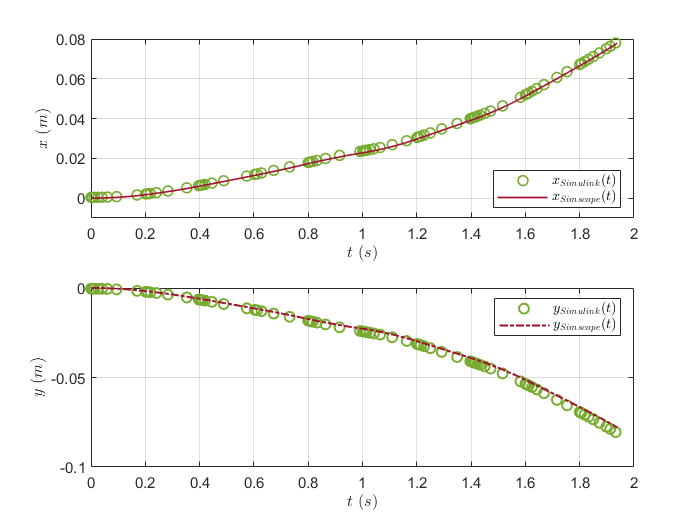

figure();
subplot(2,1,1)
plot(t(1:7:end),x1(1:7:end),'o','LineWidth',1,"Color",'#77AC30'), hold on;
plot(t,x2,'LineWidth',1,"Color",'#A2142F'), hold off;
ylabel('$x\;(m)$','Interpreter','Latex');
xlabel('$t\;(s)$','Interpreter','Latex');
ylim([-0.01 0.08])
legend('$x_{Simulink}(t)$','$x_{Simscape}(t)$','Interpreter','Latex',...
        'Location', "southeast"); grid;
subplot(2,1,2)
plot(t(1:7:end),y1(1:7:end),'o','LineWidth',1.2,"Color",'#77AC30'), hold on;
plot(t,y2,'-.','LineWidth',1.2,"Color",'#A2142F'), hold off;
ylabel('$y\;(m)$','Interpreter','Latex');
xlabel('$t\;(s)$','Interpreter','Latex');
legend('$y_{Simulink}(t)$','$y_{Simscape}(t)$','Interpreter','Latex',...
        'Location', "northeast"); grid;

Figura 6: Posição da bola no prato com relação aos eixos $x \:\:e \:\:y$.

Diante dos resultados de simulação, pode-se afirmar que a velocidade da bola no Simulink é superior à obtida com o Simscape. Isto pode ser atribuído à premissa inicial de que as forças de atrito são desprezíveis. O diagrama de blocos do Simulink despreza estas forças, no entanto, o Simscape considera um coeficiente de atrito não nulo. Ainda que a discrepância entre os valores seja pequena, a diferença de posição da bola nos dois eixos se dá pela consideração da força de atrito atuante, no caso do Simscape, e a inexistência da mesma no caso do Simulink. 

## Referências Bibliográficas

[1] A. SINGH. **Moab System Modeling and PID Controller Design.**